clear; clc;
n=4;
d=0;
A = [0, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
1, 0, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
0, 1, 0, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
0, 0, 1, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0; 
1, 0, 0, 0, 0, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0; 
0, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0; 
0, 0, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 0, 0, 0, 0; 
0, 0, 0, 1, 0, 0, 1, 0, 0, 0, 0, 1, 0, 0, 0, 0; 
0, 0, 0, 0, 1, 0, 0, 0, 0, 1, 0, 0, 1, 0, 0, 0; 
0, 0, 0, 0, 0, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 0; 
0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0; 
0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 0, 0, 0, 0, 1; 
0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 1, 0, 0; 
0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 0, 1, 0; 
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 0, 1; 
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 1, 0]

A =      0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0
     0     1     0     0     1     0     1     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     1     0     1     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     1     0     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0     0     1     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     1     0     1     0     0     1     0     0


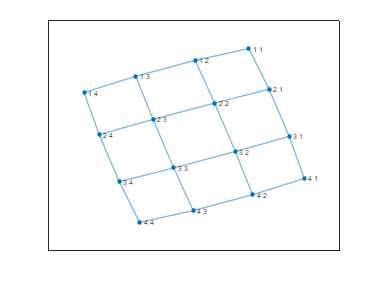

NodesNames={'1 1', '1 2', '1 3', '1 4', '2 1', '2 2', '2 3', '2 4', '3 1', '3 2', '3 3', '3 4', '4 1', '4 2', '4 3', '4 4'};
%генерация 3ёх случайных не равных друг другу чисел
s=randi(16,1);
cou=1;
B(cou)=s;
while cou~=3
    s1=randi(16,1);
    c=B==s1;
    if(sum(c)==0)
        cou=cou+1;
        B(cou)=s1;
    end
end
B=sort(B);
G=graph(A, NodesNames);
G.Edges.Weight=[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]';
plot(G);

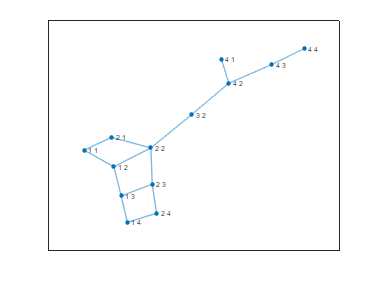

%удаление 3ёх вершин графа, т.е. расставление препятствий и представление
%соответствующего графа
G=G.rmnode(NodesNames(B(1:3)));
plot(G);

NewOrder=[1:1:(B(1)-1) (B(1)+1):1:(B(2)-1) (B(2)+1):1:(B(3)-1) (B(3)+1):1:numnodes(G)+3];
NewNodesNames=NodesNames(NewOrder);
StartNode=randi(13,1);
cou=1;
Targets(cou)=randi(13,1);
while cou~=5
    tar=randi(13,1);
    c=Targets==tar;
    if(sum(c)==0)
        cou=cou+1;
        Targets(cou)=tar;
    end
end
disp("Реализация поиска пути с помощью BFS");

Реализация поиска пути с помощью BFS


disp("Стартовая точка:")

Стартовая точка:


disp(NewNodesNames(Targets(1)));

    {'4 4'}



disp("Цели, которые необходмо посетить:")

Цели, которые необходмо посетить:


disp(NewNodesNames(Targets(2:4)));

    {'1 3'}    {'1 2'}    {'1 1'}



disp("Финальная цель");

Финальная цель


disp(NewNodesNames(Targets(5)));

    {'2 2'}



disp("Порядок обхода при BFS")

Порядок обхода при BFS


disp(NewNodesNames(G.bfsearch(Targets(1))));

    {'4 4'}    {'4 3'}    {'4 2'}    {'3 2'}    {'4 1'}    {'2 2'}    {'1 2'}    {'2 1'}    {'2 3'}    {'1 1'}    {'1 3'}    {'2 4'}    {'1 4'}



BFS=NewNodesNames(G.bfsearch(Targets(1)));
[N1,ID1]=ismember(NewNodesNames(Targets(2)),BFS);
[N2,ID2]=ismember(NewNodesNames(Targets(3)),BFS);
[N3,ID3]=ismember(NewNodesNames(Targets(4)),BFS);
[N4,ID4]=ismember(NewNodesNames(Targets(5)),BFS);
if(N1 && N2 && N3 && N4)
    disp("Все цели были пройдены и достигнута финальная точка");
    disp("Порядок прохождения целей и итоговой точки:")
    BFSorder=[ID1, ID2, ID3, ID4];
    disp(BFSorder);
    %"Далее надо рассмотреть 2 ситуации: Итоговая точка была пройдена раньше какой-либо из целевых и итоговая точка оказалась в самом конце"
    if(BFSorder(4)>BFSorder(1) && BFSorder(4)>BFSorder(2) && BFSorder(4)>BFSorder(3))
        disp("В данном случае нам достаточно одного прохода алгоритмом BFS, так как итоговая точка была найдена позже всех")
        disp("Все шаги алгоритма поиска BFS");
        disp(bfsearch(G, Targets(1), 'allevents'));
        disp("Найдём кратчайший путь, зная что агент посетил все целевй точки до финальной:");
        [SortBFSOrder, IndOfSortBFSOrder]=sort(BFSorder);        
        P1=NewNodesNames(shortestpath(G,Targets(1),Targets(1+IndOfSortBFSOrder(1))));
        P2=NewNodesNames(shortestpath(G,Targets(1+IndOfSortBFSOrder(1)),Targets(1+IndOfSortBFSOrder(2))));
        P3=NewNodesNames(shortestpath(G,Targets(1+IndOfSortBFSOrder(2)),Targets(1+IndOfSortBFSOrder(3))));
        P4=NewNodesNames(shortestpath(G,Targets(1+IndOfSortBFSOrder(3)),Targets(1+IndOfSortBFSOrder(4))));
        P=[P1 P2(2:length(P2)) P3(2:length(P3)) P4(2:length(P4))];
        disp("Весь путь:");
        disp(P);
    end
    if(BFSorder(4)<BFSorder(1) || BFSorder(4)<BFSorder(2) || BFSorder(4)<BFSorder(3))
        disp("В данном случае необходимо снова начать перебор алгоритмом BFS, так как из последней целевой точки необходимо найти путь до итоговой");
        lastTar=max(BFSorder);
        disp(NewNodesNames(G.bfsearch(BFS(lastTar))));
        disp('Предполагаем, что перебор заканчивается при достижении итоговой точки');
        disp("Все шаги алгоритма поиска BFS");
        disp("Первый прогон:");
        disp(bfsearch(G, Targets(1), 'allevents'));
        disp("Посетим сперва все целевые точки");
        TarBFSorder=BFSorder(1:3);
        [SortTarBFSOrder, IndOfSortTarBFSOrder]=sort(TarBFSorder);
        P1=NewNodesNames(shortestpath(G,Targets(1),Targets(1+IndOfSortTarBFSOrder(1))));
        P2=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarBFSOrder(1)),Targets(1+IndOfSortTarBFSOrder(2))));
        P3=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarBFSOrder(2)),Targets(1+IndOfSortTarBFSOrder(3))));
        disp("Второй прогон:");
        disp(bfsearch(G, BFS(lastTar), 'allevents'));
        P4=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarBFSOrder(3)),Targets(5)));
        P=[P1 P2(2:length(P2)) P3(2:length(P3)) P4(2:length(P4))];
        disp("Весь путь:");
        disp(P);
    end
else
    disp("Не все цели были пройдены, так как из-за исключенных точек необходимая вершина оказалась изолирована");
end

Все цели были пройдены и достигнута финальная точка


Порядок прохождения целей и итоговой точки:


    11     7    10     6



В данном случае необходимо снова начать перебор алгоритмом BFS, так как из последней целевой точки необходимо найти путь до итоговой


    {'1 3'}    {'1 2'}    {'1 4'}    {'2 3'}    {'1 1'}    {'2 2'}    {'2 4'}    {'2 1'}    {'3 2'}    {'4 2'}    {'4 1'}    {'4 3'}    {'4 4'}



Предполагаем, что перебор заканчивается при достижении итоговой точки


Все шаги алгоритма поиска BFS


Первый прогон:


         Event          Node       Edge       EdgeIndex
    ________________    ____    __________    _________

    startnode            13     NaN    NaN       NaN   
    discovernode         13     NaN    NaN       NaN   
    edgetonew           NaN      13     12        15   
    discovernode         12     NaN    NaN       NaN   
    finishnode           13     NaN    NaN       NaN   
    edgetonew           NaN      12     11        14   
    discovernode         11     NaN    NaN       NaN   
    edgetofinished      NaN      12     13        15   
    finishnode           12     NaN    NaN       NaN   
    edgetonew           NaN      11      9        12   
    discovernode          9     NaN    NaN       NaN   
    edgetonew           NaN      11     10        13   
    discovernode         10     NaN    NaN       NaN   
    edgetofinished     

Посетим сперва все целевые точки


Второй прогон:


         Event          Node       Edge       EdgeIndex
    ________________    ____    __________    _________

    startnode             3     NaN    NaN       NaN   
    discovernode          3     NaN    NaN       NaN   
    edgetonew           NaN       3      2         3   
    discovernode          2     NaN    NaN       NaN   
    edgetonew           NaN       3      4         5   
    discovernode          4     NaN    NaN       NaN   
    edgetonew           NaN       3      7         6   
    discovernode          7     NaN    NaN       NaN   
    finishnode            3     NaN    NaN       NaN   
    edgetonew           NaN       2      1         1   
    discovernode          1     NaN    NaN       NaN   
    edgetofinished      NaN       2      3         3   
    edgetonew           NaN       2      6         4   
    discovernode       

Весь путь:


    {'4 4'}    {'4 3'}    {'4 2'}    {'3 2'}    {'2 2'}    {'1 2'}    {'1 1'}    {'1 2'}    {'1 3'}    {'1 2'}    {'2 2'}



disp("Реализация поиска пути с помощью DFS")

Реализация поиска пути с помощью DFS


disp("Порядок обхода при DFS")

Порядок обхода при DFS


disp(NewNodesNames(G.dfsearch(Targets(1))));

    {'4 4'}    {'4 3'}    {'4 2'}    {'3 2'}    {'2 2'}    {'1 2'}    {'1 1'}    {'2 1'}    {'1 3'}    {'1 4'}    {'2 4'}    {'2 3'}    {'4 1'}



DFS=NewNodesNames(G.dfsearch(Targets(1)));
[N5,ID5]=ismember(NewNodesNames(Targets(2)),DFS);
[N6,ID6]=ismember(NewNodesNames(Targets(3)),DFS);
[N7,ID7]=ismember(NewNodesNames(Targets(4)),DFS);
[N8,ID8]=ismember(NewNodesNames(Targets(5)),DFS);
if(N5 && N6 && N7 && N8)
    disp("Все цели были пройдены и достигнута финальная точка");
    disp("Порядок прохождения целей и итоговой точки:")
    DFSorder=[ID5, ID6, ID7, ID8];
    disp(DFSorder);
    %"Далее надо рассмотреть 2 ситуации: Итоговая точка была пройдена раньше какой-либо из целевых и итоговая точка оказалась в самом конце"
    if(DFSorder(4)>DFSorder(1) && DFSorder(4)>DFSorder(2) && DFSorder(4)>DFSorder(3))
        disp("В данном случае нам достаточно одного прохода алгоритмом DFS, так как итоговая точка была найдена позже всех")
        disp("Все шаги алгоритма поиска DFS");
        disp(dfsearch(G, Targets(1), 'allevents'));
        disp("Найдём кратчайший путь, зная что агент посетил все целевй точки до финальной:");
        [SortDFSOrder, IndOfSortDFSOrder]=sort(DFSorder);        
        P1=NewNodesNames(shortestpath(G,Targets(1),Targets(1+IndOfSortDFSOrder(1))));
        P2=NewNodesNames(shortestpath(G,Targets(1+IndOfSortDFSOrder(1)),Targets(1+IndOfSortDFSOrder(2))));
        P3=NewNodesNames(shortestpath(G,Targets(1+IndOfSortDFSOrder(2)),Targets(1+IndOfSortDFSOrder(3))));
        P4=NewNodesNames(shortestpath(G,Targets(1+IndOfSortDFSOrder(3)),Targets(1+IndOfSortDFSOrder(4))));
        P=[P1 P2(2:length(P2)) P3(2:length(P3)) P4(2:length(P4))];
        disp("Весь путь:");
        disp(P);
    end
    if(DFSorder(4)<DFSorder(1) || DFSorder(4)<DFSorder(2) || DFSorder(4)<DFSorder(3))
        disp("В данном случае необходимо снова начать перебор алгоритмом DFS, так как из последней целевой точки необходимо найти путь до итоговой");
        lastTar=max(DFSorder);
        disp(NewNodesNames(G.dfsearch(DFS(lastTar))));
        disp('Предполагаем, что перебор заканчивается при достижении итоговой точки');
        disp("Все шаги алгоритма поиска DFS");
        disp("Первый прогон:");
        disp(dfsearch(G, Targets(1), 'allevents'));
        disp("Посетим сперва все целевые точки");
        TarDFSorder=DFSorder(1:3);
        [SortTarDFSOrder, IndOfSortTarDFSOrder]=sort(TarDFSorder);
        P1=NewNodesNames(shortestpath(G,Targets(1),Targets(1+IndOfSortTarDFSOrder(1))));
        P2=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarDFSOrder(1)),Targets(1+IndOfSortTarDFSOrder(2))));
        P3=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarDFSOrder(2)),Targets(1+IndOfSortTarDFSOrder(3))));
        disp("Второй прогон:");
        disp(dfsearch(G, DFS(lastTar), 'allevents'));
        P4=NewNodesNames(shortestpath(G,Targets(1+IndOfSortTarDFSOrder(3)),Targets(5)));
        P=[P1 P2(2:length(P2)) P3(2:length(P3)) P4(2:length(P4))];
        disp("Весь путь:");
        disp(P);
    end
else
    disp("Не все цели были пройдены, так как из-за исключенных точек необходимая вершина оказалась изолирована");
end

Все цели были пройдены и достигнута финальная точка


Порядок прохождения целей и итоговой точки:


     9     6     7     5



В данном случае необходимо снова начать перебор алгоритмом DFS, так как из последней целевой точки необходимо найти путь до итоговой


    {'1 3'}    {'1 2'}    {'1 1'}    {'2 1'}    {'2 2'}    {'2 3'}    {'2 4'}    {'1 4'}    {'3 2'}    {'4 2'}    {'4 1'}    {'4 3'}    {'4 4'}



Предполагаем, что перебор заканчивается при достижении итоговой точки


Все шаги алгоритма поиска DFS


Первый прогон:


         Event          Node       Edge       EdgeIndex
    ________________    ____    __________    _________

    startnode            13     NaN    NaN       NaN   
    discovernode         13     NaN    NaN       NaN   
    edgetonew           NaN      13     12        15   
    discovernode         12     NaN    NaN       NaN   
    edgetonew           NaN      12     11        14   
    discovernode         11     NaN    NaN       NaN   
    edgetonew           NaN      11      9        12   
    discovernode          9     NaN    NaN       NaN   
    edgetonew           NaN       9      6        10   
    discovernode          6     NaN    NaN       NaN   
    edgetonew           NaN       6      2         4   
    discovernode          2     NaN    NaN       NaN   
    edgetonew           NaN       2      1         1   
    discovernode       

Посетим сперва все целевые точки


Второй прогон:


         Event          Node       Edge       EdgeIndex
    ________________    ____    __________    _________

    startnode             3     NaN    NaN       NaN   
    discovernode          3     NaN    NaN       NaN   
    edgetonew           NaN       3      2         3   
    discovernode          2     NaN    NaN       NaN   
    edgetonew           NaN       2      1         1   
    discovernode          1     NaN    NaN       NaN   
    edgetodiscovered    NaN       1      2         1   
    edgetonew           NaN       1      5         2   
    discovernode          5     NaN    NaN       NaN   
    edgetodiscovered    NaN       5      1         2   
    edgetonew           NaN       5      6         8   
    discovernode          6     NaN    NaN       NaN   
    edgetodiscovered    NaN       6      2         4   
    edgetodiscovered   

Весь путь:


    {'4 4'}    {'4 3'}    {'4 2'}    {'3 2'}    {'2 2'}    {'1 2'}    {'1 1'}    {'1 2'}    {'1 3'}    {'1 2'}    {'2 2'}

